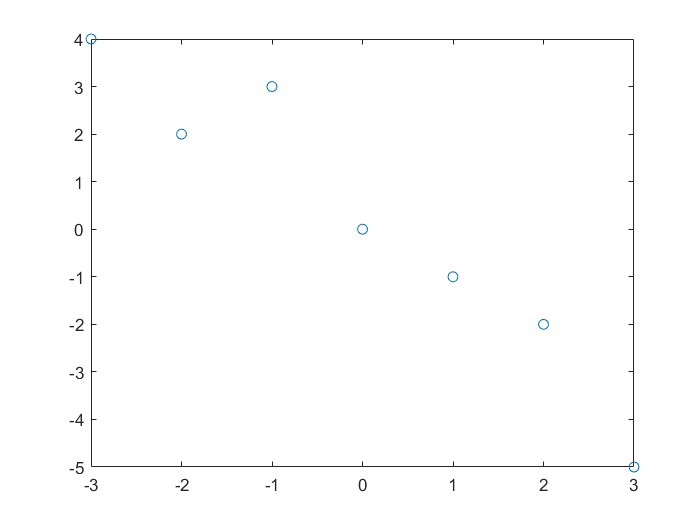

x=-3:3;
y=[4 2 3 0 -1 -2 -5];
plot(x,y,'o')

x1=[110;130;180;125;150;165;120;145;175;155];
x2=[105;125;85;145;200;160;240;260;290;270];
y=[102;99;115;75;55;95;16;78;82;90];
%cftool curve fitting

t=1:16;
y=[4 6.4 8 8.8 9.22 9.5 9.7 9.86 10 10.2 10.32 10.42 10.5 10.55 10.58 10.6]';

%规划
k=[-6;-5];
a=[5 3;6 7;0 5];
b=[100;160;180];
lb=[0;0];
[x,fval,exitflag,output]=linprog(k,a,b,[],[],lb);


Optimal
solution
found.



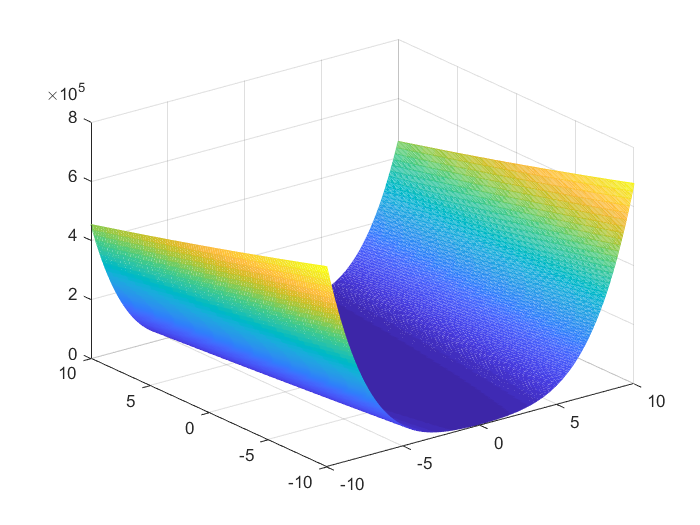

clear
x=-10:0.1:10;
y=-10:0.1:10;
[x,y]=meshgrid(x,y);
z=56*(y-x.*x).^2+(1-x).*(1-x);
mesh(x,y,z)

f=@(x)56*(x(2)-x(1).*x(1)).^2+(1-x(1)).^2;
x0=[-3;3];
[x,fval,exitflag]=fminunc(f,x0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =     0.9997
    0.9995


fval = 6.3438e-08

exitflag = 1

clear
y=@(x)exp(-x)+x.*x;
[x,fval,exitflag]=fminbnd(y,0,100)

y=@(x)-x(1)*x(2)*x(3);
a=[1 2 2;-1 -2 -2];
b=[27;0];
x0=[1;1;1];
[x,fval,exitflag]=fmincon(y,x0,a,b)

v=@(x)-pi*x(1)*x(1)*x(2);
lb=[0;0];
x0=[4;8];
nonl=@(x)deal([],2*pi*x(1)*x(2)+2*pi*x(1)^2-300);%homework
[x,fval,exitflag]=fmincon(v,x0,[],[],[],[],lb,[],nonl)

clear
y=@(x)exp(x(1))*(4*x(1)*x(1)+2*x(2)*x(2)+4*x(1)*x(2)+2*x(2)+1);
x0=[1;1];
nonl2=@(x)deal([1.5*x(1)*x(2)-x(1)-x(2);-x(1)*x(2)-10],[]);
[x,fval,exitflag]=fmincon(y,x0,[],[],[],[],[],[],nonl2)

clear
y=@(x)30*x(1)+450*x(2);
x0=[1;1];
lb=[0;0];
[x,fval,exitflag]=fmincon(y,x0,[],[],[],[],lb,[],@nonl3)

%function [c,ceq]=nonl(x)
 %   c=[];
 %   ceq=2*pi*x(1)*x(2)+2*pi*x(1)^2-300;
%end

%function [c,ceq]=nonl2(x)
 %   c(1)=1.5*x(1)*x(2)-x(1)-x(2);
 %   c(2)=-x(1)*x(2)-10;
 %   ceq=[];
%end

function [c,ceq]=nonl3(x)
    c=[];
    ceq=0.5*x(1)+x(2)*(2+0.25*x(2));
end